#### Name/Last Name: Chawakorn Chaichanawirote

#### Student ID : 59340500013

# FRA333 : Intro to Robotics

## Assignment 10: Trajectory Generation

### Problem 1: Cubic Polynomial

Given a set of via points' positions 

$q=\left\lbrack \begin{array}{ccccc}
0 & 1 & 3 & -1 & 0
\end{array}\right\rbrack$  radians

, duration between each sub-trajectroy to be

$\Delta t=\left\lbrack \begin{array}{cccc}
0\ldotp 5 & 1 & 0\ldotp 75 & 1
\end{array}\right\rbrack$ seconds

There are 5 via points in total. Assume that the velcoities at the beginning and at the end of the entire trajectory are 0 rad/s.

Determine the velocities at the rest of the via points based on the average velocity method. Then find the coefficients of each sub-trajectories using cubic spline.

Show all your works.

**Solution**

Initialize values

q = [0 1 3 -1 0];
dt = [0.5 1 0.75 1];

qdot represents velocities at each viapoint

qdot = [0 0 0 0 0];
c0 = [0 0 0 0];
c1 = [0 0 0 0];
c2 = [0 0 0 0];
c3 = [0 0 0 0];

use average velocity to find the velocities at each viapoint

for i = 1:size(qdot, 2) - 2
    qdot(i+1) = (q(i+1) - q(i))/dt(i);
end
qdot

qdot =          0    2.0000    2.0000   -5.3333         0


update weights according to

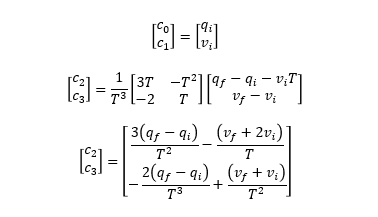

for j = 1:4
    c0(j) = q(j);
    c1(j) = qdot(j+1);
    c2(j) = 3*(q(j+1) -q(j))/(dt(j)^2) - (qdot(j+1) - 2*qdot(j))/dt(j);
    c3(j) = (2*q(j) - 2*q(j+1))/(dt(j)^3) + (qdot(j+1) + qdot(j))/(dt(j)^2);
    
end
c0

c0 =      0     1     3    -1


c1

c1 =     2.0000    2.0000   -5.3333         0


c2

c2 =     8.0000    8.0000   -8.8889   -7.6667


c3

c3 =    -8.0000         0   13.0370   -7.3333
